# Walsh-Hadamard Transform of a Signal

This example shows a simple input signal and its Walsh-Hadamard transform.

x = [19 -1 11 -9 -7 13 -15 5];
y = fwht(x)

y =      2     3     0     4     0     0    10     0


`y` contains nonzero values at locations 0, 1, 3, and 6. Form the Walsh functions with the sequency values 0, 1, 3, and 6 to recreate x.

w0 = [1 1 1 1 1 1 1 1];
w1 = [1 1 1 1 -1 -1 -1 -1];
w3 = [1 1 -1 -1 1 1 -1 -1];
w6 = [1 -1 1 -1 -1 1 -1 1];
w = y(0+1)*w0 + y(1+1)*w1 + y(3+1)*w3 + y(6+1)*w6

w =     19    -1    11    -9    -7    13   -15     5


Obtain the same result by extracting the nonzero values and Walsh functions programmatically.

ww = fwht(eye(length(y)))*length(y)

ww =      1     1     1     1     1     1     1     1
     1     1     1     1    -1    -1    -1    -1
     1     1    -1    -1    -1    -1     1     1
     1     1    -1    -1     1     1    -1    -1
     1    -1    -1     1     1    -1    -1     1
     1    -1    -1     1    -1     1     1    -1
     1    -1     1    -1    -1     1    -1     1
     1    -1     1    -1     1    -1     1    -1


nz = find(y);
w = sum(y(nz)'.*ww(nz,:))

w =     19    -1    11    -9    -7    13   -15     5


xxx0 =testDan1.Dan.XYZg.YawAcc;
n=1000

n = 1000

xxx1 = xxx0(n: n+64)

xxx1 =    -0.1574   -0.1624   -0.1669   -0.1724   -0.1841   -0.1932   -0.2050   -0.2144   -0.2202   -0.2230   -0.2238   -0.2237   -0.2237   -0.2238   -0.2239   -0.2233   -0.2221   -0.2199   -0.2192   -0.2199   -0.2233   -0.2279   -0.2328   -0.2369   -0.2405   -0.2437   -0.2468   -0.2502   -0.2541   -0.2586   -0.2634   -0.2682   -0.2728   -0.2772   -0.2814   -0.2853   -0.2890   -0.2924   -0.2968   -0.3012   -0.3048   -0.3076   -0.3097   -0.3118   -0.3142   -0.3167   -0.3191   -0.3211   -0.3234   -0.3259


y = abs(fwht(xxx1))

y =     0.1391    0.1332    0.0286    0.0227    0.0042    0.0017    0.0134    0.0075    0.0022    0.0037    0.0038    0.0020    0.0020    0.0039    0.0106    0.0047    0.0020    0.0039    0.0037    0.0022    0.0020    0.0039    0.0045    0.0014    0.0027    0.0032    0.0033    0.0026    0.0027    0.0032    0.0065    0.0006    0.0033    0.0026    0.0026    0.0033    0.0029    0.0030    0.0030    0.0029    0.0030    0.0029    0.0028    0.0031    0.0033    0.0026    0.0026    0.0033    0.0025    0.0033


y1=y(1:65)'

y1 =     0.1391
    0.1332
    0.0286
    0.0227
    0.0042
    0.0017
    0.0134
    0.0075
    0.0022
    0.0037


y2=mnogMatr*y1

y2 = 0.0860

n=8

n = 8

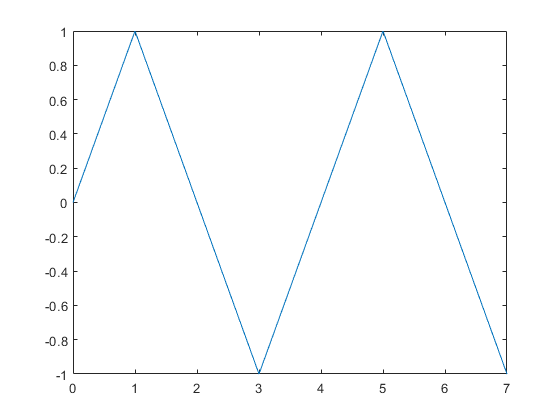

t=linspace(0, n-1, n);
w0=2*pi*2;
sig = sin(w0/n*t);
plot(t, sig)

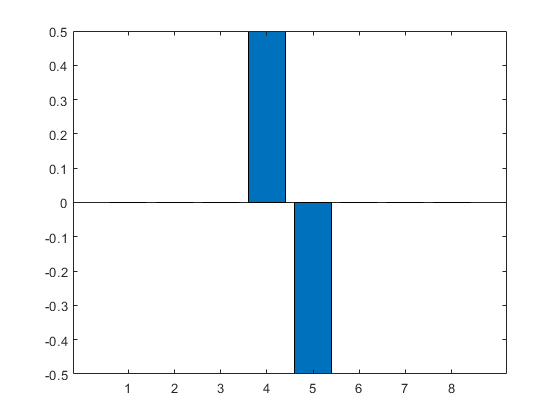

y = fwht(sig);
y0 = abs(y);
bar(y)

yy=sqrt(pow2(y(4))+pow2(y(5)))

yy = 1.4565

n=16

n = 16

H = hadamard(n)

H =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1
     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1
     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1
     1     1     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1
     1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1
     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1     1     1
     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1     1    -1
     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1
     1    -1     1    -1     1    -1     1    -1    -1     1    -1     1    -1     1    -1     1


nn=64

nn = 64

y=zeros(nn);
ww = fwht(eye(length(y)))*length(y)

ww =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1  